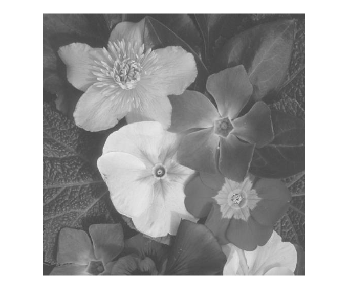

I = imread("flower.jpg");
imshow(I)

#### A função imadjust satura os pixels baseada nos limites superior e inferior

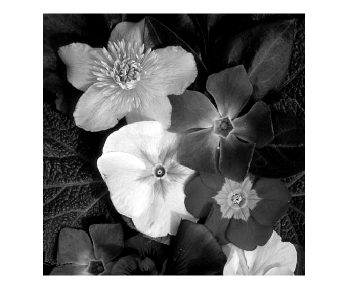

A = imadjust(I, [0.3, 0.89]);
imshow(A)

#### A função stretchlim retorna o limite superior e inferior da imagem

lowhigh = stretchlim(G)

lowhigh =     0.2784
    0.8784


#### Os pixels abaixo do limite inferior são trazidos para baixo, na imagem em escala de cinza os pixels se tornam mais escuros

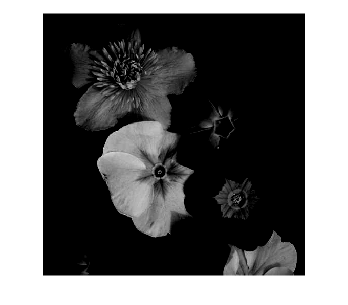

A = imadjust(I, [0.6, 1]);
imshow(A)

#### Os pixels acima do limite superior são trazidos para cima, na imagem em escala de cinza os pixels se tornam mais claros

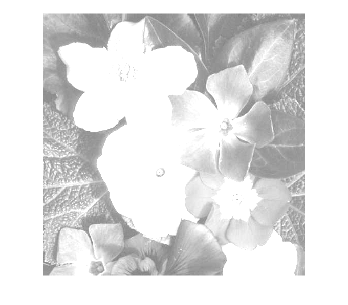

A = imadjust(I, [0, 0.5]);
imshow(A)

B(:,:,1) = I;
B(:,:,2) = I;
B(:,:,3) = I;
imshow(B)

#### A função funciona da mesma forma com os canais rgb, na imagem os canais azul e vermelho tem limites superiores menores trazendo seus valores pra cima e deixando a imagem arroxeada

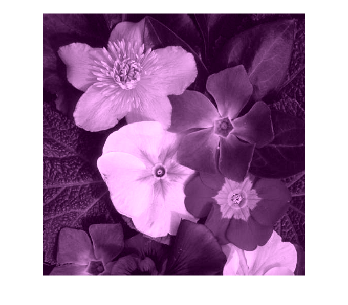

A = imadjust(B, [0.2 0.3 0.2 ; 0.8 1 0.8],[]);
imshow(A)

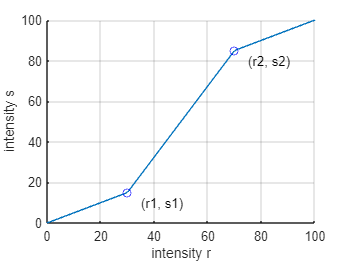

figure, hold on
l = 100;
x = linspace(0,l);
P = [30, 15 ; 70, 85];

y = stretch_transform(x, P(1,:), P(2,:), l);

plot(x, y);
xlabel("intensity r");
ylabel("intensity s")

plot(P(:,1), P(:,2),'bo')
text(P(:,1)+5, P(:,2)-5, ["(r1, s1)", "(r2, s2)"])
grid()
hold off

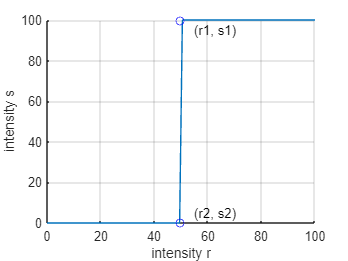

figure, hold on
l = 100;
x = linspace(0,l);
r = 50;
P = [r, 0 ; r, l];

y = limiar_transform(x, r, l);

plot(x, y);
xlabel("intensity r");
ylabel("intensity s")

plot(P(:,1), P(:,2), 'bo')
text(r+5, l-5, "(r1, s1)")
text(r+5, 5, "(r2, s2)")
grid()
hold off

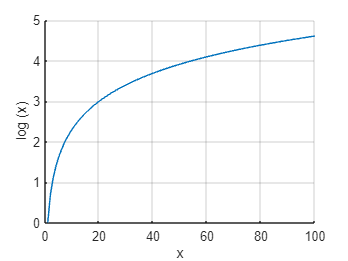

figure, hold on
x = linspace(0,l);
y = log_transform(x);
plot(x,y)
xlabel("x");
ylabel("log (x)")
grid()
hold off

function y = log_transform(x)
    y = log(x);
end 

function y = stretch_transform(xs, p1, p2, l)
    y = zeros(1,size(xs,2));
    i = 0;
    for x = xs
        i = i + 1;
        if x <= p1(1)
            y(i) = x * p1(2) / p1(1);
            continue
        end
        if x > p1(1) && x <= p2(1)
            p = p2 - p1;
            y(i) = p1(2) + (x-p1(1)) * p(2) / p(1);
            continue
        end
        p = [l,l] - p2;
        y(i) = (l - p(2)) + (x-p2(1)) * p(2) / p(1);
    end
end

function y = limiar_transform(xs, r, l)
    y = zeros(1,size(xs,2));
    i = 0;
    for x = xs
        i = i + 1;
        if x < r
            y(i) = 0;
        else
            y(i) = l;
        end
    end 
end